# Praktikum 1 - Shift 2 Kamis - Kunci Jawaban

`9 September 2021`

`Nama : ``Asisten Praktikum `

`NIM  :`

## Nomor 1

Jelaskan perbedaan antara data dengan tipe *string* dan *char* pada MATLAB !

**Jawaban :**

String pada MATLAB dipandang sebagai suatu elemen tunggal, sedangkan character adalah array yang terdiri dari barisan abjad atau angka. 

String di define dengan menggunakan *double quote mark* , contoh : "string". Sedangkan char didefinisikan dengan menggunakan single quote mark, e.g 'char'.

Kita tidak bisa memodifikasi elemen - elemen tunggal dari string (karena string sendiri dianggap sebagai sebuah unit tunggal, walaupun string tersebut terdiri dari banyak sekali karakter). Berbeda dengan char, dimana pada char kita dapat mengakses setiap individu elemennya seperti array.

## Nomor 2

a. Bangunlah plot seperempat lingkaran dengan $x^2 +y^2 =1,0\le x,y\le 1$ dengan garis putus-putus warna biru.

b. Pada badan *plot* yang sama, bangkitkan 1000 titik secara acak *uniform *pada ruang $(0,1)\times(0,1)$. Plot titik-titik ini:

    - dengan lingkaran merah jika titiknya terletak di dalam atau pada batasan lingkaran

    - dengan silang biru jika titiknya terletak di luar lingkaran.

*Contoh:*

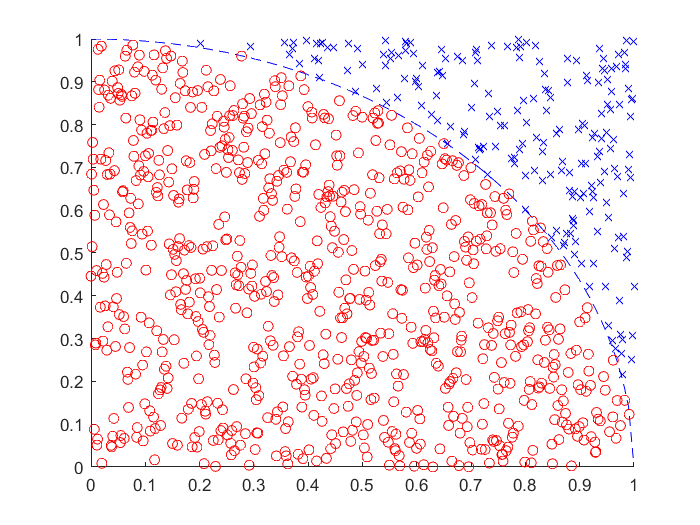

% Tulis jawaban anda dibawah garis
% --------------------------------
figure
hold on;
x = linspace(0, 1);
plot(x, sqrt(1 - x.^2), 'b--');
x_r = linspace(0, 1, 1000);
y = rand(1, 1000);
d = sqrt(x_r.^2 + y.^2);
plot(x_r(d <= 1), y(d <= 1), 'ro')
plot(x_r(d > 1), y(d > 1), 'bx')

**Tips** :

1) Apakah untuk sebuah *array,* kita bisa memilih semua anggotanya yang memenuhi suatu syarat?

2) Apakah fungsi dari perintah *hold on*?

## Nomor 3

Budi ingin membuat sebuah mesin yang dapat menerjemahkan penulisan angka dalam `char` menjadi nilai sebenarnya dari tulisan tersebut (`integer`)

Contoh :

- Masukan : **'sebelas'**, Keluaran : **11**

- Masukan : **'tujuh belas'**, Keluaran : **17**

- Masukan : **'tujuh puluh tujuh'**, Keluaran : **77**

Bangun fungsi tersebut pada file `convertAngka.m`, dengan input berupa `char` dan keluaran bilangan bulat atau `integer. `

**Batasan** : Bilangan bulat di interval $\left\lbrack 1,99\right\rbrack$.

% Cek jawaban disini
x = 'tujuh ratus tujuh puluh tujuh';
disp(convertAngka(x))

   777



**Tips :**

1.Untuk menghindari *kuli* , anda dapat menggunakan fitur `Map Containers` MATLAB sebagai berikut

dimana `keySet` berperan sebagai kunci, dan `valueSet` adalah nilai dari kunci tersebut.

Contoh, apabila kita ingin mengakses nilai dari key Budi, dapat dilakukan dengan menuliskan : `M('Budi')`